# Sensitivity Analysis with MATLAB for  Student Competition Scores

In the current blog post, we will explore the concept of sensitivity analysis and its significance in engineering design. Our attention will be on the student competition score function, especially competitions focused on model aircraft design, i.e. AIAA Design Build Fly, SAE AeroDesign, etc, as a case study to investigate how distinctive design variables affect the mission score. To demonstrate this, we will use the scoring function, from the  [AIAA 2026-2027 Rule Book](https://aiaa.org/wp-content/uploads/2026/09/DBF-2027-Rules-Draft.pd) , with MATLAB plotting approach By the end of the blog, you will better understand how to make informed design choices to optimize the competition score. Enjoy!

## What is Sensitivity Analysis?

Sensitivity Analysis (SA) is a technique used to measure the impact of uncertainties in input variables on output variables in a model. SA aims to determine which input variables impact the output most and identify the range of values in which the model is most sensitive. This information helps to design a robust model with reduced uncertainties. 

SA is practiced in a range of fields, including but not limited to finance, engineering, and economics. Specifically, in the field of engineering design, it helps engineers optimize their designs and to improve the quality, reliability, and performance of the system. Although several SA methods exist, such as Univariate SA, Multivariate SA, Local SA, and Global SA, the first two are widely used in engineering design.  Model aircraft design competitions, such as the [AIAA DBF](https://www.aiaa.org/dbf/example-dbf-feature) and [SAE Aero Design](https://www.sae.org/attend/student-events/sae-aero-design-east/), are no exception. SA is used here specifically to evaluate score sensitivity. It helps teams identify the most sensitive design variables and optimize their vehicle designs to maximize their score.

## Competition Problem Statement

**Competition Problem Statement (2026–27 Season)**

The objective for the 2026–27 AIAA DBF contest is to design, build, and test a UAV with a towed sensor. Missions include delivery of the UAV, transportation of sensors in shipping containers, and surveillance by deploying, operating, and recovering a towed sensor.   

Teams must complete 3 flight missions and 1 ground mission. The mission score for each mission is as follows:

Mission 1 (Staging Flight):                            $\textrm{M1}=1\ldotp 0$                 for successful completion (or automatically satisfied by a successful Mission 2)

Mission 2 (Delivery Flight):                          $\textrm{M2}=1+\left\lbrack \frac{N_{\left(\frac{\textrm{Weight}}{\textrm{Time}}\right)} }{{\textrm{Max}}_{\left(\frac{\textrm{Weight}}{\textrm{Time}}\right)} }\right\rbrack$    (transporting sensor in shipping container plus optional simulators over 5 laps within 5 minutes).   

Mission 3 (Sensor Flight):                           $\textrm{M3}=\;2+\frac{N\_\;\left(\left.\textrm{#laps}\;*\textrm{sensor}\;\textrm{weight}\right)\right)}{\textrm{Max}\_\;\left(\left.\textrm{#laps}\;*\;\textrm{sensor}\;\textrm{weight}\right)\right)}$     (deploying, changing light modes, and recovering the sensor)

Ground Mission (Container Drop Test):       $\textrm{GM}=0\ldotp 5+\left\lbrack \frac{N_{\left(\textrm{Weight}*\textrm{Height}\right)} }{{\textrm{Max}}_{\left(\textrm{Weight}*\textrm{Height}\right)} }\right\rbrack$  (6 drop tests on a concrete floor within a 5-minute time limit). 

Total Mission Score:                                  $\textrm{TMS}\;=\textrm{M1}+\textrm{M2}+\textrm{M3}+\textrm{GM}$

Competition Score:                                    ($\left.\textrm{Total}\;\textrm{Report}\;\textrm{Score}*\textrm{Total}\;\textrm{Mission}\;\textrm{Score}\;\right)+\textrm{Participation}$

All missions need to be completed as per the flight course shown in Figure 1.

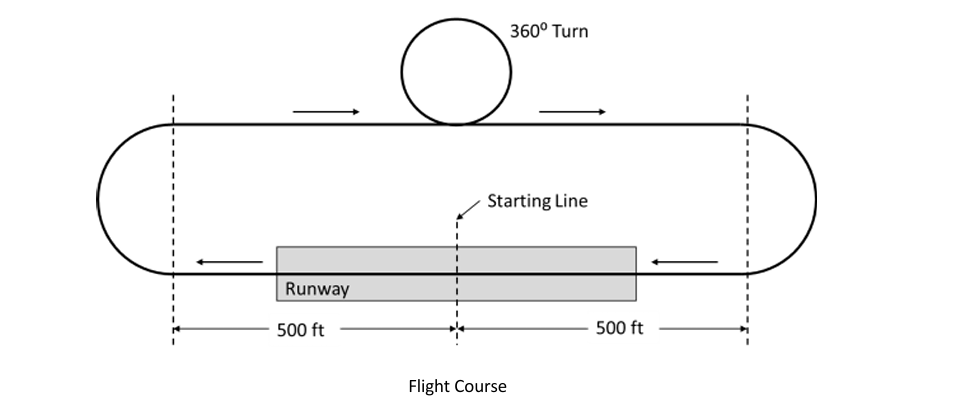

*Figure **1: Flight Course*

## Score Sensitivity Analysis with Plotting Approach in MATLAB

## 1.1 Total Mission Score Analysis

The total mission score depends on multiple missions with different objectives and performance metrics. From the rule structure, it can be inferred that:

- **Mission 1 (Staging Flight)** requires completing 3 laps with no payload. It can also be automatically satisfied by a successful Mission 2, making it a baseline gate rather than a variable optimization target.   

- **Mission 2 (Delivery Flight)** evaluates the total weight of the sensor shipping container and optional simulators flown divided by the total flight time for 5 laps. Minimizing flight time while maximizing container payload drives the design toward an efficient, high-speed cargo configuration.   

- **Mission 3 (Sensor Flight)** scales with the number of laps flown multiplied by the sensor weight (Laps × Sensor Weight) while executing remote deployment, light-mode sequencing, and recovery.   

- **Ground Mission (GM)** evaluates container drop survival over 6 drops (2 drops on each of 3 sides determined by a die roll) scaled by sensor weight and drop height, governed by structural integrity and quick-rigging time limits. 

% Defining parameters for the best-performing team (2026-27 Season Baseline)
bestTeam.SensorWeight = 2.0;    % in lbs (maximum declared weight of the sensor)
bestTeam.ContainerWeight = 5.0; % in lbs (weight of shipping container + rigging)
bestTeam.Simulators = 4;        % in numbers (optional M2 container simulators)
bestTeam.M2_Weight = bestTeam.ContainerWeight + (bestTeam.Simulators * 5.0); % total M2 weight
bestTeam.M2_Time = 150.0;       % in seconds (total flight time for 5 laps in Mission 2)
bestTeam.M3_Laps = 10;          % in numbers (number of laps completed in Mission 3)
bestTeam.DropHeight = 60.0;     % in inches (maximum declared drop height up to 60 in)
bestTeam.GM_Time = 120.0;       % in seconds - NOT used in the score (the 5-minute Ground Mission limit is pass/fail only)


To define mission score functions, and to calculate the maximum mission score, individual teams’ parameters can be considered equivalent to the best-performing team. 

% Defining parameters for the team
team = bestTeam;

As per the [AIAA 2026-2027 Rule Book](https://aiaa.org/wp-content/uploads/2026/09/DBF-2027-Rules-Draft.pd) , mission scores can be formulated as follows:

% Mission score formulation as per 2026-27 AIAA DBF Rules
score.Max.M1 = 1.0; 
score.Max.M2 = 1 + ( (team.M2_Weight / team.M2_Time) / (bestTeam.M2_Weight / bestTeam.M2_Time) );
score.Max.M3 = 2 + ( (team.M3_Laps * team.SensorWeight) / (bestTeam.M3_Laps * bestTeam.SensorWeight) );
score.Max.GM = 0.5 + ( (team.SensorWeight * team.DropHeight) / (bestTeam.SensorWeight * bestTeam.DropHeight) );
score.Max.Total = score.Max.M1 + score.Max.M2 + score.Max.M3 + score.Max.GM;                                 % Total Maximum Mission Score                                                                   % total maximum mission score

For Mission 1, the score is awarded only on a successful flight. Also, it does not affect any other parameters. Hence, Mission 1 can be eliminated for sensitivity analysis. 

To perform the sensitivity analysis, each score is varied in a change. Here, a change vector is needed which varies parameters from -50% to +50%.

% Change vector to perform SA
change = -0.5:0.1:0.5;

The effect of the sensitivity of each mission score on the total score is studied as follows:

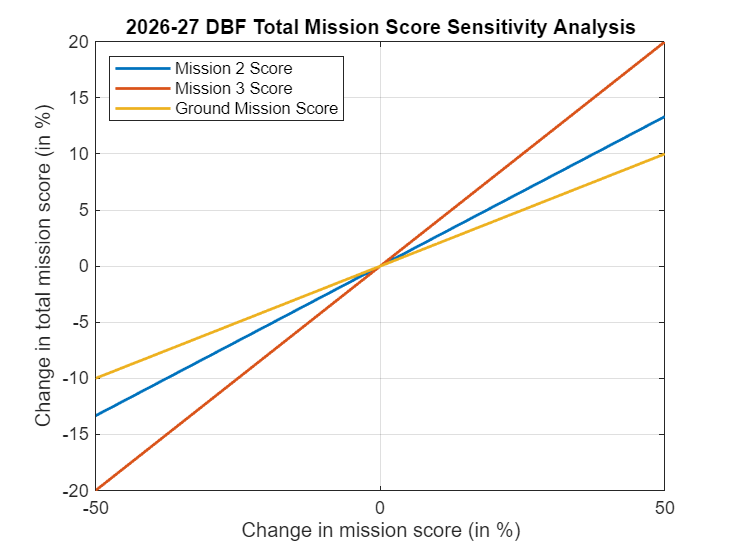

% Impact of Mission 2 score on Total Mission Score
score.Total.M2 = score.Max.M1 + score.Max.M2*(1 + change) + score.Max.M3 + score.Max.GM;
score.Total.Change.M2 = (score.Total.M2 - score.Max.Total)/score.Max.Total * 100;

% Impact of Mission 3 score on Total Mission Score
score.Total.M3 = score.Max.M1 + score.Max.M2 + score.Max.M3*(1 + change) + score.Max.GM;
score.Total.Change.M3 = (score.Total.M3 - score.Max.Total)/score.Max.Total * 100;

% Impact of Ground Mission score on Total Mission Score
score.Total.GM = score.Max.M1 + score.Max.M2 + score.Max.M3 + score.Max.GM*(1 + change);
score.Total.Change.GM = (score.Total.GM - score.Max.Total)/score.Max.Total * 100;

% Plotting sensitivity analysis results
plots.Y1.Name = {'Mission 2 Score', 'Mission 3 Score', 'Ground Mission Score'};
plots.Y1.Value = [score.Total.Change.M2; score.Total.Change.M3; score.Total.Change.GM];

figure();
plot(change * 100, plots.Y1.Value', 'LineWidth', 1.5);
legend(plots.Y1.Name, 'Location', 'NorthWest');
xlabel('Change in mission score (in %)');
ylabel('Change in total mission score (in %)');
title('2026-27 DBF Total Mission Score Sensitivity Analysis');
grid on;

In the above plot, the higher the slope, the more sensitive the mission score is to variations. Hence, the following inferences can be made from the plot:

- **Mission 3** has the largest impact on the total mission score because it carries the largest share of the score (3 out of 7.5), so a given percentage change in Mission 3 moves the total the most.

- **Mission 2** has the second largest impact (2 out of 7.5), driven heavily by the trade-off between carrying heavy container payloads/simulators and maintaining a fast flight time over 5 laps.   

- **Mission 2** performance depends on two primary factors: total payload weight (shipping container + optional simulators) and total flight time.   

- **Mission 3** depends on two key design variables: sensor weight and the number of completed laps.   

- **Ground Mission** has the smallest share of the three (1.5 out of 7.5) in this macro-view, but remains critical as its score depends directly on sensor weight and drop height, and the mission must be completed within the 5-minute assembly and rigging time limit.   

- To explore optimization further, univariate sensitivity analysis can be performed on individual sub-variables (like flight speed vs. weight) for Mission 2 and Mission 3.

### 1.2    Mission-2 Score Analysis

For Mission 2, the total payload weight (shipping container plus optional container simulators) and flight time for 5 laps are the two key parameters to be evaluated as follows:

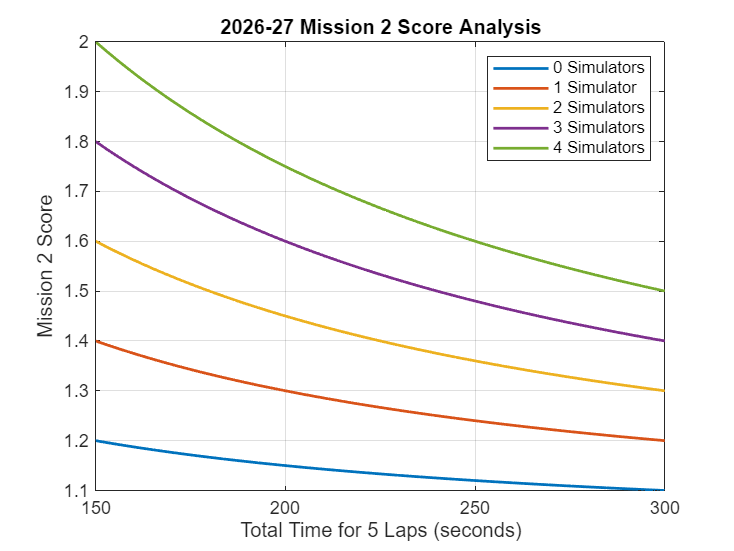

% Defining flight time vector for 5 laps for the team (ranging from fast to slow, e.g., 150s to 300s)
team.Array.FlightTime = [linspace(150, 300, 50)]';

% Univariate SA for Mission 2 score with flight time and number of container simulators
% Assuming loaded container weight = 4 lbs, and each simulator has the same weight as the container (5 curves evaluated)
simulators_vector = [0, 1, 2, 3, 4]; 
container_base_weight = 4.0; %must be the same weight simulator
simulator_unit_weight = 4.0;

% Constructing weight matrix corresponding to simulator variations across flight times
team.Array.Weight = container_base_weight + (simulators_vector * simulator_unit_weight); 

% Best team reference benchmark values
bestTeam.M2_Weight = container_base_weight + (4 * simulator_unit_weight); % max simulators (20 lbs)
bestTeam.M2_Time = 150; % seconds for 5 laps

% Calculating M2 score array: M2 = 1 + (Weight/Time) / (BestWeight/BestTime)
score.Array.M2 = 1 + (team.Array.Weight ./ team.Array.FlightTime) / (bestTeam.M2_Weight / bestTeam.M2_Time);

plots.Y2.Value = score.Array.M2;
plots.Y2.Name = {'0 Simulators', '1 Simulator', '2 Simulators', '3 Simulators', '4 Simulators'};

% Plotting sensitivity analysis plot for Mission 2
figure();
plot(team.Array.FlightTime, plots.Y2.Value, 'LineWidth', 1.5)
legend(plots.Y2.Name, 'Location', 'NorthEast')
xlabel('Total Time for 5 Laps (seconds)')
ylabel('Mission 2 Score')
title('2026-27 Mission 2 Score Analysis')
grid on; 

In the above plot, the slope of the curves is negative, showing that faster flight times yield higher scores. Furthermore, the separation between curves demonstrates that payload weight scales your baseline score multiplier. Hence, the following engineering inferences can be made:   

- **Payload Mass (Simulators)** heavily scales your maximum attainable Mission 2 score; carrying more container simulators shifts the entire score curve upward.

- **Flight Time** has an inverse relationship with score; because the slope is negative, reducing your 5-lap flight time directly increases your score.   

- Minimizing aerodynamic drag and maximizing propulsion power are critical because adding payload weight increases wing loading, which can degrade turn performance and lap times unless managed through efficient aircraft sizing.

- A heavier aircraft carrying maximum container simulators *only* outperforms a lighter aircraft if its flight time penalty over 5 laps is kept minimal.

### 1.3    Mission-3 Score Analysis

For Mission 3, sensor weight and the number of laps are the key parameters to be evaluated. The effect of both variables on the Mission 3 score can be studied as follows: 

#### 1.3.1    Number of Laps and Sensor Weight Correlation (2D plot)

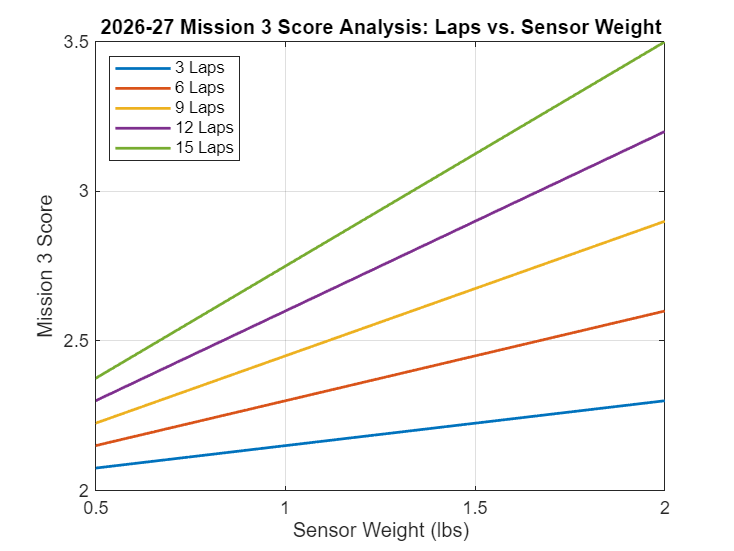

% Defining sensor weight vector for the team (from 0.5 lbs up to max bestTeam sensor weight)
team.Array.SensorWeight = [linspace(0.5, bestTeam.SensorWeight, 50)]';

% Univariate SA for Mission 3 score with number of laps and sensor weight variation
team.Array.Laps = [3:3:15].*ones(50,5); % Evaluating 3, 6, 9, 12, and 15 laps

% Scoring formula: M3 = 2 + (Laps * SensorWeight) / (BestLaps * BestSensorWeight)
score.Array.M3.Laps2Weight = 2 + (team.Array.Laps .* team.Array.SensorWeight) / (bestTeam.M3_Laps * bestTeam.SensorWeight);

plots.Y3.Value = score.Array.M3.Laps2Weight;
plots.Y3.Name = {'3 Laps', '6 Laps', '9 Laps', '12 Laps', '15 Laps'};

% Plotting sensitivity analysis plot for Mission 3
figure();
plot(team.Array.SensorWeight, plots.Y3.Value, 'LineWidth', 1.5)
legend(plots.Y3.Name, 'Location', 'NorthWest')
xlabel('Sensor Weight (lbs)')
ylabel('Mission 3 Score')
title('2026-27 Mission 3 Score Analysis: Laps vs. Sensor Weight')
grid on;

The above plot shows that the slope of the curve is positive and increases with a greater number of laps, meaning higher lap counts amplify the scoring leverage of sensor weight. Hence, the following inferences can be made:   

- **Sensor Weight** acts as a direct multiplier; increasing the sensor weight scales the score upward linearly, with higher lap counts producing steeper, more sensitive response curves.   

- **Number of Laps** significantly shifts your baseline M3 score upward. Maximizing laps completed within the 5-minute flight window yields a higher score multiplier.   

- Designing a robust aircraft capable of carrying a heavier sensor while maintaining efficient turn performance to maximize lap count provides the optimal strategy for Mission 3 dominance.

#### 1.3.2   Sensor Weight and Drop Height Trade-Off Analysis

Under the 2026–2027 rules, the Ground Mission score is a direct function of sensor weight multiplied by the drop height ($W_{\textrm{Sensor}\;} *H_{\textrm{Drop}}$). Because sensor weight is also the primary driver in Mission 3, teams face a direct structural trade-off: declaring a heavier sensor and higher drop height increases points across both missions, but increases the risk of structural failure during drop tests. The correlation across drop height variations is evaluated below:   

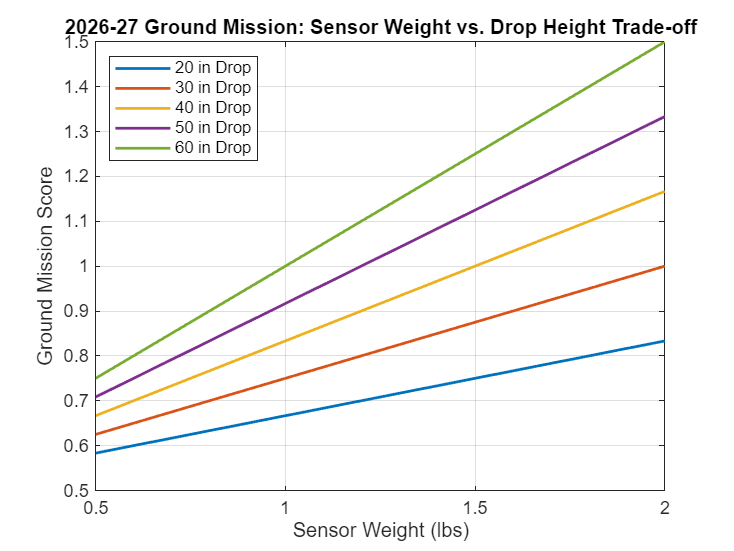

% Defining sensor weight vector for the team (lbs)
team.Array.SensorWeightGM = [linspace(0.5, bestTeam.SensorWeight, 50)]';

% Univariate SA for Ground Mission score with sensor weight and drop height variation
% Evaluating drop heights: 20, 30, 40, 50, and 60 inches
drop_heights = [20, 30, 40, 50, 60];
team.Array.DropHeights = drop_heights .* ones(50, 5);

% Scoring formula: GM = 0.5 + (SensorWeight * DropHeight) / (BestSensorWeight * BestDropHeight)
GM_Weight2Height = 0.5 + (team.Array.SensorWeightGM .* team.Array.DropHeights) / (bestTeam.SensorWeight * bestTeam.DropHeight);

plots.Y4.Value = GM_Weight2Height;
plots.Y4.Name = {'20 in Drop', '30 in Drop', '40 in Drop', '50 in Drop', '60 in Drop'};
% Plotting sensitivity analysis plot for Ground Mission Trade-off
figure();
plot(team.Array.SensorWeightGM, plots.Y4.Value, 'LineWidth', 1.5)
legend(plots.Y4.Name, 'Location', 'NorthWest')
xlabel('Sensor Weight (lbs)')
ylabel('Ground Mission Score')
title('2026-27 Ground Mission: Sensor Weight vs. Drop Height Trade-off')
grid on;

It can be inferred from the above plot that declaring a maximum 60-inch drop height combined with a heavy sensor yields the highest possible Ground Mission score multiplier. However, because any structural damage or light failure during the 6 drop tests results in a complete mission score penalty of zero, teams must design their shipping container dampening systems to withstand high-g drop shocks before committing to maximum height settings.

#### 1.3.3    Sensor Weight and Number of Laps 3D Correlation

Keeping other variables constant, the interaction between **sensor weight** and **number of laps** can be evaluated simultaneously. For this purpose, a MATLAB 3D surface plot provides a clear representation of how both parameters jointly scale the Mission 3 score.

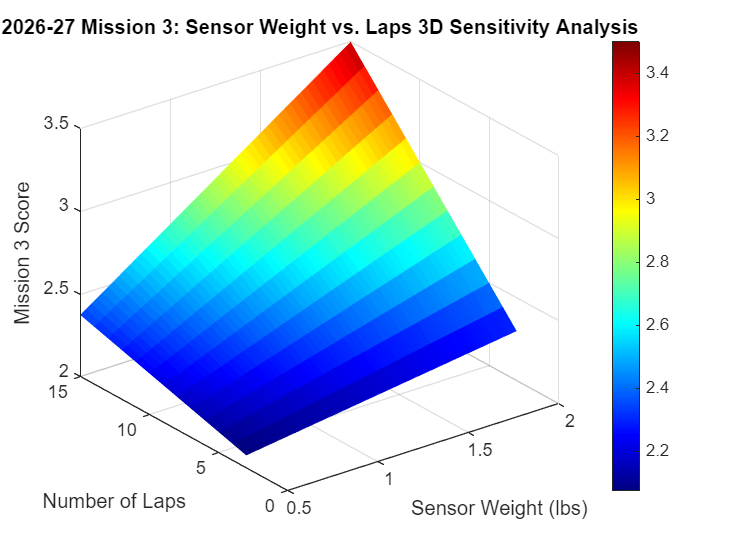

% Defining vectors for sensor weight and number of laps
weight_vector = linspace(0.5, bestTeam.SensorWeight, 50);
laps_vector = 3:15; % Evaluating lap counts from 3 to 15

% Preparing mesh grid for 3D plot
[X_weight, Y_laps] = meshgrid(weight_vector, laps_vector);

% Scoring formula: M3 = 2 + (Laps * SensorWeight) / (BestLaps * BestSensorWeight)
M3_3D_Score = 2 + (Y_laps .* X_weight) / (bestTeam.M3_Laps * bestTeam.SensorWeight);

% Plotting 3D surface plot for Mission 3 sensitivity analysis
figure();
surface(X_weight, Y_laps, M3_3D_Score, 'EdgeColor', 'none')
colormap('jet');
colorbar;

view(3);
xlabel('Sensor Weight (lbs)');
ylabel('Number of Laps');
zlabel('Mission 3 Score');
title('2026-27 Mission 3: Sensor Weight vs. Laps 3D Sensitivity Analysis');
grid on;

The above 3D surface plot shows that the Mission 3 score scales dynamically as both sensor weight and lap count increase. Since Mission 3 is proportional to the product of laps and sensor weight, both variables have the same relative effect on the score: a 10% increase in either one increases the ratio term by 10%. The difference in surface steepness comes from the different axis ranges (3 to 15 laps vs. 0.5 to 2 lbs), not from the scoring formula. Therefore, the design priority between them depends on which one is easier to improve: a faster, lower-drag aircraft for more laps, or a stronger structure and propulsion system for a heavier sensor.

## Summary

From the scoring sensitivity analysis conducted for the 2026–2027 AIAA Design, Build, Fly competition, it can be inferred that:

- **Mission 3** has the largest impact on the total mission score, as it carries the largest share of the score (3 out of 7.5).   

- **Sensor weight** and **number of laps** have the same relative effect on Mission 3 (their product sets the score), and sensor weight also drives the Ground Mission; they are followed by **flight time** and **container payload simulators** in Mission 2.   

- Balancing aircraft aerodynamic efficiency (maintaining fast flight times over 5 laps) with high payload capacity (carrying maximum shipping container simulators and heavy sensors) is essential to maximizing total scores.   

- Rigorous structural design of the shipping container is mandatory to withstand maximum height drop tests (up to 60 inches), ensuring zero structural damage or electrical light failures that would otherwise result in a complete ground mission score penalty.   

In this analysis, we utilized a MATLAB plotting framework to evaluate design space sensitivity, identify high-leverage variables, and establish quantitative targets for our aircraft design.